x=1:29

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29


for i = 1:simulate
     [income(i),each_cost(i,:)] = Pbl4eachCost(result(i,:)');
     plot(x, each_cost(i,:)/1e4, 'LineWidth', 1);

end
writematrix(result,"第四问蒙特卡洛模拟结果.txt")
writematrix(income,"第四问蒙特卡洛模拟利润")
writematrix(each_cost,"第四问蒙特卡洛模拟成本")

grid on
each_cost/1e4

ans =     2.0000    8.0000    6.0000    2.0000    8.0000    6.0000    8.0000    6.0000    1.0875         0    2.1732    1.0932    1.0919    2.1938    1.0854    2.1738    7.8872    7.9112    7.8768    3.5972    3.5880    3.5968    7.1240         0    3.4920         0         0         0         0
    2.0000    8.0000    6.0000    2.0000    8.0000    6.0000    8.0000    6.0000    1.0897    1.0872    2.1928    1.0891         0    2.1906    1.0915    2.1730    7.8744    7.8880    7.8760    3.5884    3.5876    3.5920    7.1544         0    3.7600         0         0         0         0
    2.0000    8.0000    6.0000    2.0000    8.0000    6.0000    8.0000    6.0000    1.0898         0    2.1738    1.0905         0    2.1764    1.0891    2.1858    7.8816    7.8912    7.9128    3.5932    3.5928    3.6000    7.1752         0    3.3760         0         0         0         0
    2.0000    8.0000    6.0000    2.0000    8.0000    6.0000    8.0000    6.0000    1.0962    1.0914    2.1886    1.0899 

var_cost =  mean(var((each_cost/1e4)))

var_cost = 0.0202

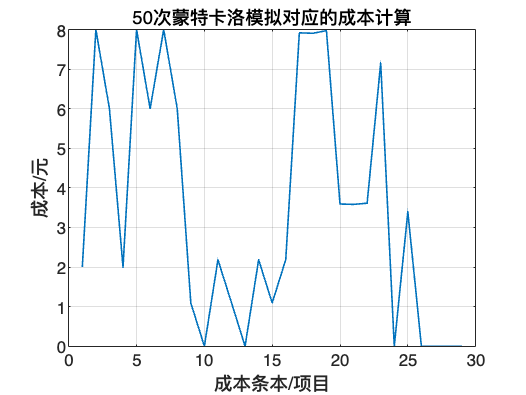

xlabel("成本条本/项目")
ylabel("成本/元")
title("50次蒙特卡洛模拟对应的成本计算")

var(income/1e4)

ans = 1.4371

plot(1:50,income/1e4)